clear all
DATA=dlmread('industry1.txt');
Ymax=100;
Xmax=100;
gates=DATA(1,1);
nets=DATA(1,2);
pads=DATA(gates+2,1);
X=zeros(pads,1);
Y=zeros(pads,1);
padtonet=zeros(pads);
C=zeros(gates);
bx=zeros(gates,1);
by=zeros(gates,1);
for i =1:gates
   for j=1:DATA(i+1,2)
       t=DATA(i+1,j+2);
       for k =i+1:gates
           for l=1:DATA(k+1,2)
               if t==DATA(k+1,l+2)
                       C(i,k)=1;
                       C(k,i)=1;
               end
           end
       end

   end
end

for i=1:pads
    padtonet(i,1)=DATA(gates+2+i,2);
    X(i,1)=DATA(gates+2+i,3);
    Y(i,1)=DATA(gates+2+i,4);
end

A=-C;
for i =1:pads
    for j=1:gates
        for k=1:DATA(j+1,2)
            if padtonet(i,1)==DATA(j+1,k+2)
                A(j,j)=1+sum(C(j,:));
                bx(j,1)=X(i,1);
                by(j,1)=Y(i,1);
            end
        end
        if A(j,j)==0
            A(j,j)=sum(C(j,:));
        end
    end
end

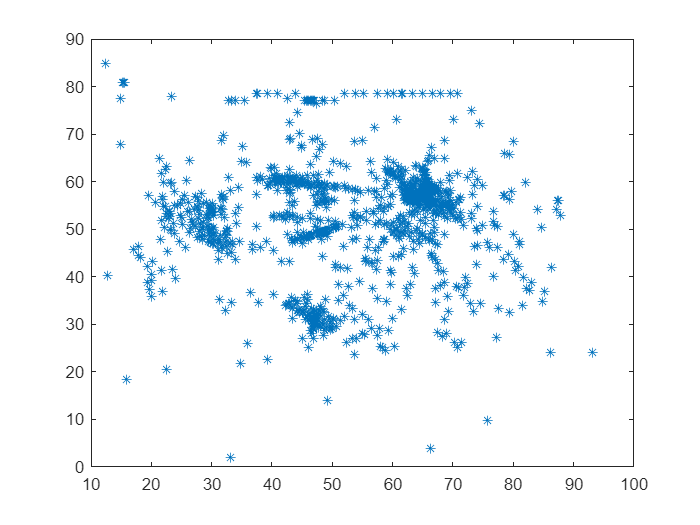

x=A\bx;
y=A\by;
plot(x,y,'*');

middle=median(x);
left=0;
right=0;
for i=1:gates
    if middle>=x(i,1)
        if left==0
            left=i;
        else
            left=[left;i];
        end
    else
        if right==0
            right=i;
        else
            right=[right;i];
        end
    end
end

C=zeros(size(left,1));
A=zeros(size(left,1));
bx1=zeros(size(left,1),1);
by1=zeros(size(left,1),1);
for i =1:size(left,1)
   for j=1:DATA(left(i,1)+1,2)
       t=DATA(left(i,1)+1,j+2);
       for k =1:size(left,1)
           for l=1:DATA(left(k,1)+1,2)
               if t==DATA(left(k,1)+1,l+2)
                   if left(k,1)~=left(i,1)
                       C(i,k)=1;
                   end
                end
            end
        end
   end
end
A=-C;

## pads

for i=1:size(X,1)
    if X(i,1)>=Xmax/2
        X1(i,1)=Xmax/2;
    else
        X1(i,1)=X(i,1);
    end
end

for i =1:pads
    for j=1:size(left,1)
        for k=1:DATA(left(j,1)+1,2)
            if padtonet(i,1)==DATA(left(j,1)+1,k+2)
                A(j,j)=1+sum(C(j,:));
                bx1(j,1)=X1(i,1);
                by1(j,1)=Y(i,1);
            end
        end
        if A(j,j)==0
            A(j,j)=sum(C(j,:));
        end
    end
end
for i =1:size(right,1)
   for j=1:DATA(right(i,1)+1,2)
       t=DATA(right(i,1)+1,j+2);
       for k =1:size(left,1)
           for l=1:DATA(left(k,1)+1,2)
               if t==DATA(left(k,1)+1,l+2)
                   if left(k,1)~=right(i,1)
                        A(k,k)=A(k,k)+1;
                        if bx1(k,1)==0
                            bx1(k,1)=Xmax/2;
                        end
                        if by1(k,1)==0
                           by1(k,1)=y(left(k,1),1);  
                        end 
                   end
                end
            end
        end
   end
end
bx1

bx1 =     50
    50
    50
    50
    50
    50
    50
    50
    50
    50


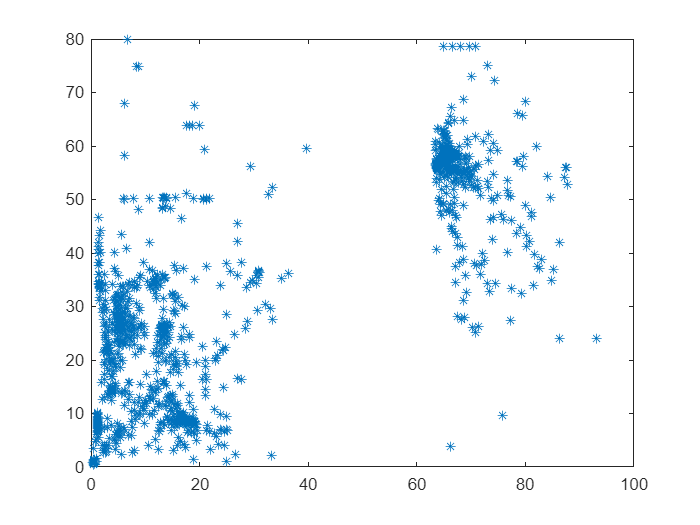

x1=A\bx1;
y1=A\by1;
for i=1:size(left,1)
    x(left(i,1),1)=x1(i,1);
end
for i=1:size(left,1)
    y(left(i,1),1)=y1(i,1);
end


plot(x,y,'*');

## QP3

%%%
C=zeros(size(right,1));
A=zeros(size(right,1));
bx2=zeros(size(right,1),1);
by2=zeros(size(right,1),1);
for i =1:size(right,1)
   for j=1:DATA(right(i,1)+1,2)
       t=DATA(right(i,1)+1,j+2);
       for k =1:size(right,1)
           for l=1:DATA(right(k,1)+1,2)
               if t==DATA(right(k,1)+1,l+2)
                   if right(k,1)~=right(i,1)
                       C(i,k)=1;
                   end
                end
            end
        end
   end
end
A=-C;
for i=1:size(X,1)
    if X(i,1)<=Xmax/2
         X1(i,1)=Xmax/2;
    else
       X1(i,1)=X(i,1);
    end
end
X1

X1 =     50
    50
    50
    50
    50
    50
    50
    50
    50
    50


for i =1:pads
    for j=1:size(right,1)
        for k=1:DATA(right(j,1)+1,2)
            if padtonet(i,1)==DATA(right(j,1)+1,k+2)
                A(j,j)=1+sum(C(j,:));
                bx2(j,1)=X1(i,1);
                by2(j,1)=Y(i,1);
            end
        end
        if A(j,j)==0
            A(j,j)=sum(C(j,:));
        end
    end
end
bx2

bx2 =     90
   100
   100
   100
   100
   100
   100
   100
   100
   100


for i =1:size(left,1)
   for j=1:DATA(left(i,1)+1,2)
       t=DATA(left(i,1)+1,j+2);
       for k =1:size(right,1)
           for l=1:DATA(right(k,1)+1,2)
               if t==DATA(right(k,1)+1,l+2)
                   if right(k,1)~=left(i,1)
                        A(k,k)=A(k,k)+1;
                        if bx2(k,1)==0
                            bx2(k,1)=x(right(k,1),1);
                        end
                        if by2(k,1)==0
                           by2(k,1)=y(right(k,1),1);  
                        end
                   end
                end
            end
        end
   end
end
bx2

bx2 =     90
   100
   100
   100
   100
   100
   100
   100
   100
   100


x2=A\bx2;
for i=x2'
    if i>50
        display(i)
    end
end

i = 51.1525

i = 54.9652

i = 63.4576

i = 50.8873

i = 50.9812

i = 51.6302

i = 52.3797

i = 50.5452

i = 62.7676

i = 83.0681

i = 66.1362

i = 56.9857

i = 58.6217

i = 58.6219

i = 56.8304

i = 56.8297

i = 51.1302

i = 56.5354

i = 52.0362

i = 50.0655

i = 52.4658

i = 63.6786

i = 63.6786

i = 63.6786

i = 56.2872

i = 68.1651

i = 61.5552

i = 56.2796

i = 55.5485

i = 55.0679

i = 62.0692

i = 55.0761

i = 53.6342

i = 60.2367

i = 65.9883

i = 53.4273

i = 67.7746

i = 56.6787

i = 53.9450

i = 60.4990

i = 60.4544

i = 59.7059

i = 54.5654

i = 51.8288

i = 55.0204

i = 56.5531

i = 62.3894

i = 63.7313

i = 59.5222

i = 64.2223

i = 63.5205

i = 67.2429

i = 69.8204

i = 71.8109

i = 72.6996

i = 71.6399

i = 50.7171

i = 72.2090

i = 55.6233

i = 55.7928

i = 61.6794

i = 52.7722

i = 50.9305

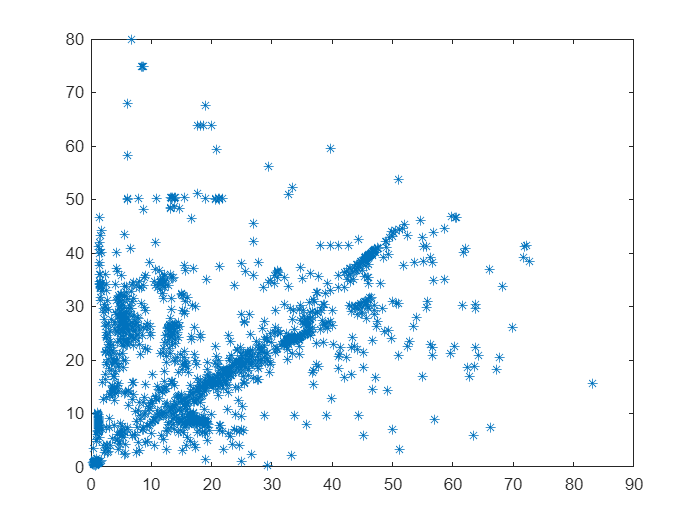

y2=A\by2;

for i=1:size(right,1)
    x(right(i,1),1)=x2(i,1);
end
for i=1:size(right,1)
    y(right(i,1),1)=y2(i,1);
end
plot(x,y,'*')

middle=median(y);
left=0;% left equaals down
right=0;% right equals to up
for i=1:gates
    if middle<=y(i,1)
        if left==0
            left=i;
        else
            left=[left;i];
        end
    else
        if right==0
            right=i;
        else
            right=[right;i];
        end
    end
end

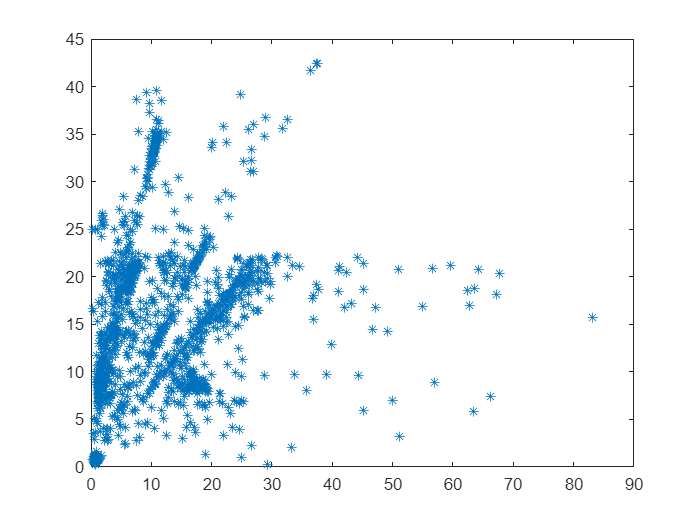

C=zeros(size(left,1));
A=zeros(size(left,1));
bx3=zeros(size(left,1),1);
by3=zeros(size(left,1),1);
for i =1:size(left,1)
   for j=1:DATA(left(i,1)+1,2)
       t=DATA(left(i,1)+1,j+2);
       for k =1:size(left,1)
           for l=1:DATA(left(k,1)+1,2)
               if t==DATA(left(k,1)+1,l+2)
                   if left(k,1)~=left(i,1)
                       C(i,k)=1;
                   end
                end
            end
        end
   end
end
A=-C;
for i=1:size(X,1)
    if Y(i,1)>=Ymax/2
        y1(i,1)=Ymax/2;
    else
       Y1(i,1)=Y(i,1);
    end
end

for i =1:pads
    for j=1:size(left,1)
        for k=1:DATA(left(j,1)+1,2)
            if padtonet(i,1)==DATA(left(j,1)+1,k+2)
                A(j,j)=1+sum(C(j,:));
                bx1(j,1)=X1(i,1);
                by1(j,1)=Y(i,1);
            end
        end
        if A(j,j)==0
            A(j,j)=sum(C(j,:));
        end
    end
end
for i =1:size(right,1)
   for j=1:DATA(right(i,1)+1,2)
       t=DATA(right(i,1)+1,j+2);
       for k =1:size(left,1)
           for l=1:DATA(left(k,1)+1,2)
               if t==DATA(left(k,1)+1,l+2)
                   if left(k,1)~=right(i,1)
                        A(k,k)=A(k,k)+1;
                        bx3(k,1)=x(k,1);
                        by3(k,1)=Ymax/2;
                   end
                end
            end
        end
   end
end
x3=A\bx3;
y3=A\by3;
for i=1:size(left,1)
    x(left(i,1))=x3(i,1);
end
for i=1:size(left,1)
    y(left(i,1))=y3(i,1);
end
plot(x,y,'*');

count=0

count = 0

for i=x'
    if i<50 
       count=count+1;
    end
end
count

count = 2256